### `CA #1: Ghazal Mousavi-810100259`

`Q1:Non-coherent detection in Rayleigh fading channel vs AWGN channel`

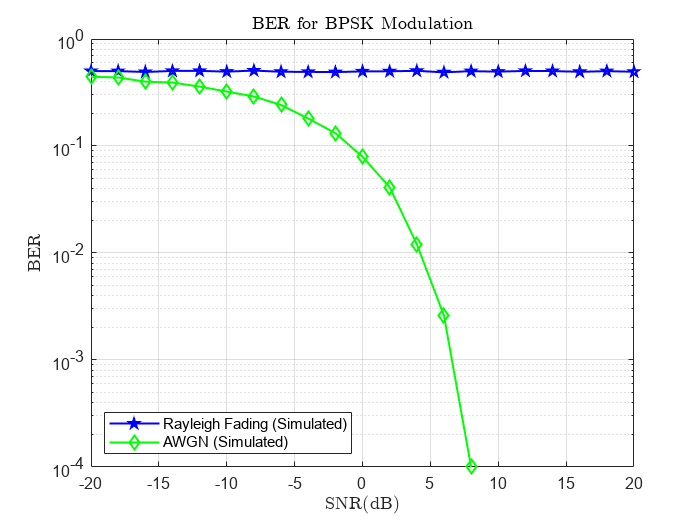

M = 2; % BPSK
K = 1e4;
snr_dB = -20:2:20;

ber_fading = zeros(length(snr_dB), 1);
ber_awgn = zeros(length(snr_dB), 1);

for j = 1 : length(snr_dB)
    % ----- Transmitter -----
    x_bits = randi([0, 1], K, 1);  
    [x, bpsk_gray_matrix, constellation_point]  = mapping(x_bits, 'bpsk', M);
    Es = mean(abs(x).^2);
    N0 = Es / 10^(snr_dB(j) / 10);

    % ----- Channel -----
    h_fading = (randn(K, 1) + 1j*randn(K, 1)) / sqrt(2);
    h_awgn = 1;
    noise = (randn(K, 1) + 1j*randn(K, 1)) / sqrt(2);
    y_fading = h_fading.*x + noise*sqrt(N0);
    y_awgn = h_awgn.*x + noise*sqrt(N0);

    % ----- ِDetection -----
    x_hat_fading = demapping(y_fading, bpsk_gray_matrix, constellation_point, "psk");
    x_hat_awgn = demapping(y_awgn, bpsk_gray_matrix, constellation_point, "psk");

    % -----Bit Error Rate -----
    ber_fading(j) = sum(x_bits(:) ~= x_hat_fading(:))/ K;
    ber_awgn(j) = sum(x_bits(:) ~= x_hat_awgn(:))/ K;
end

% -----Plot -----
figure
semilogy(snr_dB, ber_fading,'bp-','LineWidth',1.2);
hold on
semilogy(snr_dB, ber_awgn,'gd-','LineWidth', 1.2);
legend('Rayleigh Fading (Simulated)', 'AWGN (Simulated)', 'Location', 'southwest');
grid on
title('BER for BPSK Modulation', 'Interpreter', 'latex')
xlabel('SNR(dB)', 'Interpreter', 'latex')
ylabel('BER', 'Interpreter', 'latex')

` Q2: Binary Pulse Position Modulation:`

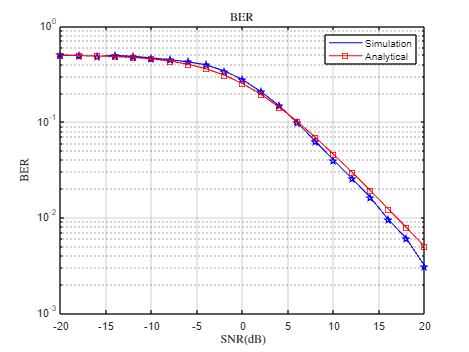

ber_simulation = zeros(length(snr_dB), 1);
ber_analytical = zeros(length(snr_dB), 1);

for j = 1 : length(snr_dB)
    % ----- Transmitter -----
    x_bits = randi([0, 1], K, 1);  
    [x, gray_matrix, constellation_point]  = mapping(x_bits, 'odd-even', M);
    Es = mean(mean(abs(x).^2));
    N0 = Es / 10^(snr_dB(j) / 10);

    % ----- Channel -----
    h = (rand(2, K) + 1j*rand(2, K)) / sqrt(2);
    noise = (randn(2, K) + 1j*randn(2, K)) / sqrt(2);
    y = h.*x.' + noise*sqrt(N0/2);

    % ----- ِDetection -----
    x_hat = demapping(y, gray_matrix, constellation_point, "odd-even");
   
    % -----Simulated BER and Analytical BER-----
    ber_simulation(j) = sum(x_bits(:) ~= x_hat(:))/ K;
    ber_analytical(j) = 1 / (2 * (1 + 10^(snr_dB(j) / 10)));
end

% ----- Plot -----
figure
semilogy(snr_dB, ber_simulation,'bp-','LineWidth',1);
hold on
semilogy(snr_dB, ber_analytical,'rs-','LineWidth',1);
legend('Simulation', 'Analytical')
grid on
title('BER ', 'Interpreter', 'latex')
xlabel('SNR(dB)', 'Interpreter', 'latex')
ylabel('BER', 'Interpreter', 'latex')

` Q3: Coherent Detection detection in Rayleigh fading channel:`

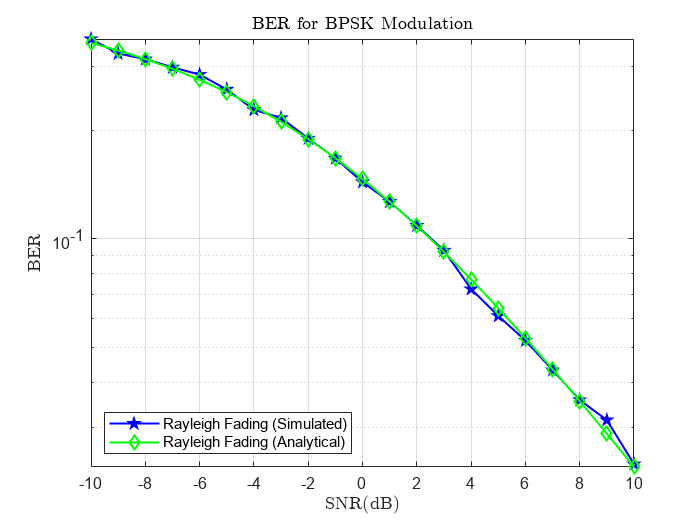

snr_dB = -10:1:10;

ber_fading = zeros(length(snr_dB), 1);
ber_pulse = zeros(length(snr_dB), 1);

for j = 1 : length(snr_dB)
    % ----- Transmitter -----
    x_bits = randi([0, 1], K, 1);  
    [x_rayleigh, bpsk_gray_matrix, constellation_point]  = mapping(x_bits, 'bpsk', M);
    Es = mean(abs(x_rayleigh).^2);
    N0 = Es / 10^(snr_dB(j) / 10);

    % -----Rayleigh Fading Channel -----
    h_fading = (randn(K, 1) + 1j*randn(K, 1)) / sqrt(2);
    noise_fading = (randn(K, 1) + 1j*randn(K, 1)) / sqrt(2);
    y_fading = h_fading.*x_rayleigh + noise_fading*sqrt(N0);
    y_fading = y_fading ./ h_fading;

    % -----BPSK Detection -----
    x_hat_fading = demapping(y_fading, bpsk_gray_matrix, constellation_point, "psk");
    
    % ----- BER -----
    ber_fading(j) = sum(x_bits(:) ~= x_hat_fading(:))/ K;

    % ----- BPPM -----
    [x_pulse, gray_matrix, ~]  = mapping(x_bits, 'odd-even', M);
    
    % -----BPPM Channel -----
    h_pulse = (rand(2, K) + 1j*rand(2, K)) / sqrt(2); 
    noise_pulse = (randn(2, K) + 1j*randn(2, K)) / sqrt(2);
    y = h_pulse.*x_pulse.' + noise_pulse*sqrt(N0/2);

    % -----BPPM Detection -----
    x_hat_pulse = demapping(y, gray_matrix, constellation_point, "odd-even");

    % -----BPPM BER -----
    ber_pulse(j) = sum(x_bits(:) ~= x_hat_pulse(:))/ K;
end

% -----Analytical BER -----
snr_linear = 10.^(snr_dB / 10);
ber_rayleigh_analytical = 0.5 * (1 - sqrt(snr_linear ./ (1 + snr_linear)));

% -----Plot Simulated vs Analytical-----
figure
semilogy(snr_dB, ber_fading,'bp-','LineWidth',1.2);
hold on
semilogy(snr_dB, ber_rayleigh_analytical,'gd-','LineWidth', 1.2);
legend('Rayleigh Fading (Simulated)', 'Rayleigh Fading (Analytical)', 'Location', 'southwest');
grid on
title('BER for BPSK Modulation', 'Interpreter', 'latex')
xlabel('SNR(dB)', 'Interpreter', 'latex')
ylabel('BER', 'Interpreter', 'latex')

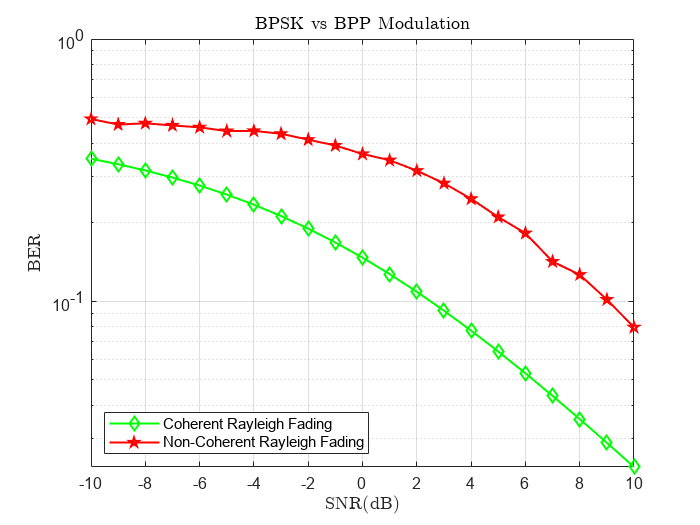

% -----Plot Rayleigh Fading using BPSK Moulation vs BPP Modulation-----
figure
semilogy(snr_dB, ber_rayleigh_analytical,'gd-','LineWidth', 1.2);
hold on
semilogy(snr_dB, ber_pulse,'rp-','LineWidth', 1.2);
legend('Coherent Rayleigh Fading', 'Non-Coherent Rayleigh Fading', 'Location', 'southwest');
grid on
title('BPSK vs BPP Modulation', 'Interpreter', 'latex')
xlabel('SNR(dB)', 'Interpreter', 'latex')
ylabel('BER', 'Interpreter', 'latex')

ratio = ber_pulse(end) / ber_fading(end);
ratio_dB1 = 10*log10(ratio)

ratio_dB1 = 5.2507

`Q4: Coherent Detection detection QPSK Modulation:`

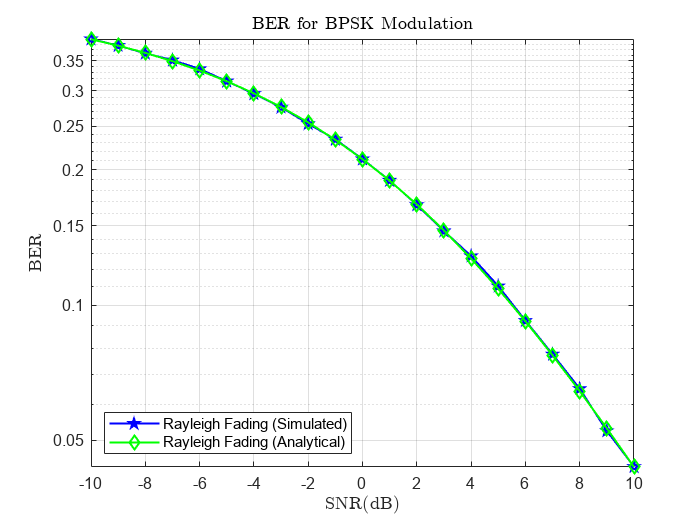

M = 4; % BPSK
K = 1e5;
snr_dB = -10:1:10;

ber_fading = zeros(length(snr_dB), 1);

for j = 1 : length(snr_dB)

    % ----- Transmitter -----
    x_bits = randi([0, 1], K, 2);  
    [x_rayleigh, bpsk_gray_matrix, constellation_point]  = mapping(x_bits, 'qpsk', M);
    Es = mean(abs(x_rayleigh).^2);
    N0 = Es * 10^(-snr_dB(j) / 10);

    % -----Rayleigh Fading Channel -----
    h_fading = (randn(K, 1) + 1j*randn(K, 1)) / sqrt(2);
    noise_fading = (randn(K, 1) + 1j*randn(K, 1)) / sqrt(2);
    y_fading = h_fading.*x_rayleigh + noise_fading*sqrt(N0);
    y_fading = y_fading ./ h_fading;

    % -----BPSK Detection -----
    x_hat_fading = demapping(y_fading, bpsk_gray_matrix, constellation_point, "qpsk");
    
    % ----- BER -----
    ber_fading(j) = sum(x_bits(:) ~= x_hat_fading(:))/ (2*K);

end

% -----Analytical BER -----
snr_linear = 10.^(snr_dB / 10);
ber_rayleigh_analytical = 0.5 * (1 - sqrt(snr_linear ./ (2 + snr_linear)));

ber_pulse = 1 ./ (2 * (1 + snr_linear /2));


% -----Plot Simulated vs Analytical-----
figure
semilogy(snr_dB, ber_fading,'bp-','LineWidth',1.2);
hold on
semilogy(snr_dB, ber_rayleigh_analytical,'gd-','LineWidth', 1.2);
legend('Rayleigh Fading (Simulated)', 'Rayleigh Fading (Analytical)', 'Location', 'southwest');
grid on
title('BER for BPSK Modulation', 'Interpreter', 'latex')
xlabel('SNR(dB)', 'Interpreter', 'latex')
ylabel('BER', 'Interpreter', 'latex')

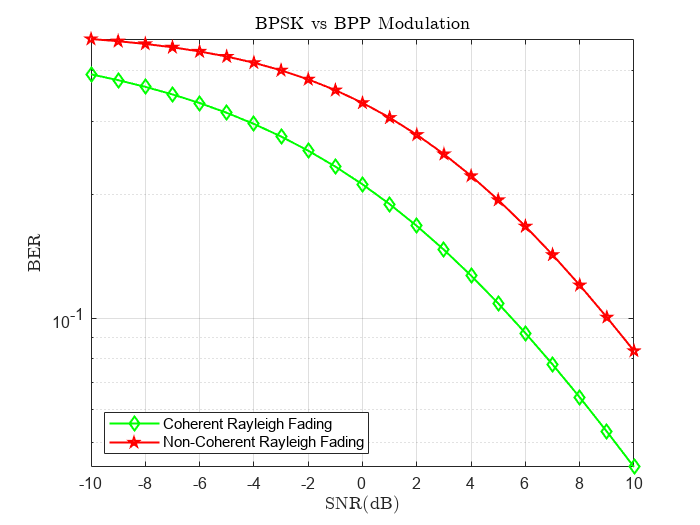

% -----Plot Rayleigh Fading using BPSK Moulation vs BPP Modulation-----
figure
semilogy(snr_dB, ber_rayleigh_analytical,'gd-','LineWidth', 1.2);
hold on
semilogy(snr_dB, ber_pulse,'rp-','LineWidth', 1.2);
legend('Coherent Rayleigh Fading', 'Non-Coherent Rayleigh Fading', 'Location', 'southwest');
grid on
title('BPSK vs BPP Modulation', 'Interpreter', 'latex')
xlabel('SNR(dB)', 'Interpreter', 'latex')
ylabel('BER', 'Interpreter', 'latex')

ratio = ber_pulse(end) / ber_fading(end);
ratio_dB = 10*log10(ratio)

ratio_dB = 2.8098

` Q5: Time Diversity:`

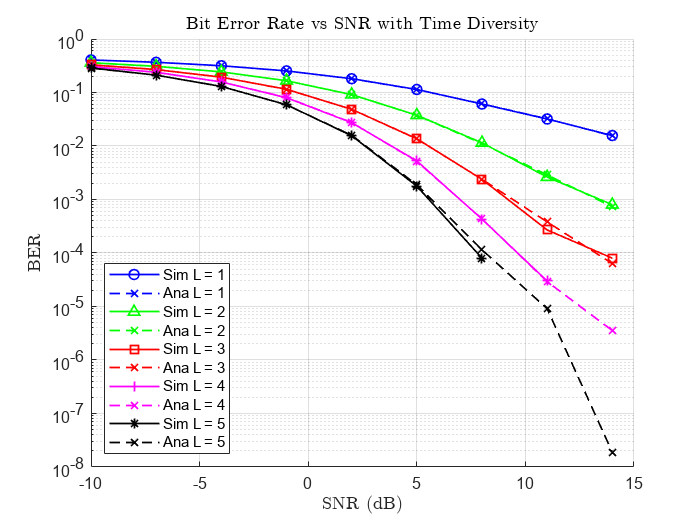

clc; clear; close all

%% Time Diversity:

M = 2; % BPSK
K = 10;
snr_dB = -10:3:15;
max_itr = 1e4;

L_vals = 1:5;

ber_mean_analytical = zeros(length(snr_dB), length(L_vals));
ber_mean_simulation = zeros(length(snr_dB), length(L_vals));

for l = 1:length(L_vals)
    L = L_vals(l);
    ber_analytical = zeros(length(snr_dB), max_itr);
    ber_simulation = zeros(length(snr_dB), max_itr);
    for itr = 1:max_itr
        for j = 1 : length(snr_dB)
            % ----- Transmitter -----
            x_bits = randi([0, 1], K, 1);  
            [x, bpsk_gray_matrix, bpsk_constellation]  = mapping(x_bits, 'bpsk', M);
            Es = mean(abs(x).^2);
            N0 = Es / 10^(snr_dB(j) / 10);
    
            % ----- Channel -----
            h = (rand(L, 1) + 1j*rand(L, 1)) / sqrt(2);
            noise = (randn(L, K) + 1j*randn(L, K)) / sqrt(2);
            y = h*x.' + noise*sqrt(N0);
    
            % ----- Analytical BER -----
            ber_analytical(j, itr) = ber_time_diversity(h, N0);
            
            % ----- Receiver (MRC Co-phasing) -----
            Y = sum(conj(h) .* y, 1);
            x_hat = demapping(Y.', bpsk_gray_matrix, bpsk_constellation, "psk");
            
            % ----- Simulated BER -----
            ber_simulation(j, itr) = sum(x_bits(:) ~= x_hat(:))/ K;    
        end
    end
    ber_mean_analytical(:, l) = mean(ber_analytical, 2);
    ber_mean_simulation(:, l) = mean(ber_simulation, 2);
end

% -----Plot-----
figure;
hold on;
colors = 'bgrmk';  
markers = 'o^s+*'; 

for i = 1:length(L_vals)
    
    plot(snr_dB, ber_mean_simulation(:, i), ...
        [colors(i) markers(i) '-'], 'LineWidth', 1, ...
        'DisplayName', sprintf('Sim L = %d', L_vals(i)));
    
    plot(snr_dB, ber_mean_analytical(:, i), ...
        [colors(i) 'x--'], 'LineWidth', 1, ...
        'DisplayName', sprintf('Ana L = %d', L_vals(i)));
end
set(gca, 'YScale', 'log');
grid on;
title('Bit Error Rate vs SNR with Time Diversity', 'Interpreter', 'latex');
xlabel('SNR (dB)', 'Interpreter', 'latex');
ylabel('BER', 'Interpreter', 'latex');
legend('Location', 'southwest');

`Q6: Alamouti Code:`

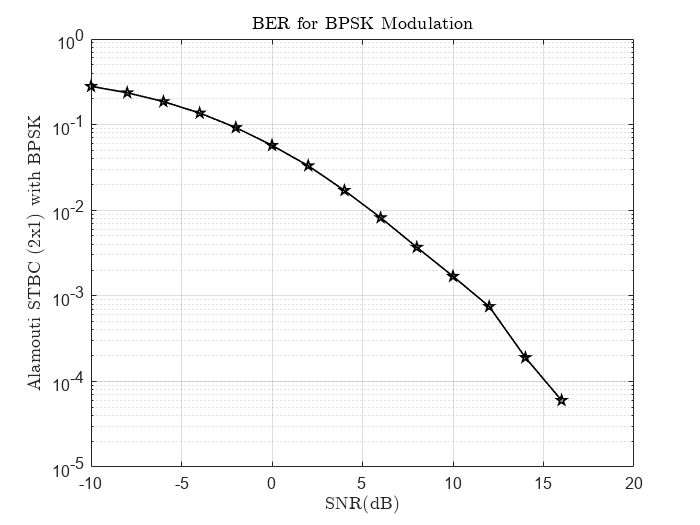

M = 2; % BPSK
K = 1e5; 
snr_dB = -10:2:16;

ber = zeros(length(snr_dB), 1);

for j = 1:length(snr_dB)
    x_bits = randi([0, 1], K, 1);
    [x_symbols, bpsk_gray_matrix, bpsk_constellation] = mapping(x_bits, 'bpsk', M);

    x_symbols = reshape(x_symbols, 2, []);  
    N_blocks = size(x_symbols, 2);

    s1 = x_symbols(1, :); % First symbol of each Alamouti block
    s2 = x_symbols(2, :); % Second symbol of each Alamouti block

    Es = mean(abs(s1).^2 + abs(s2).^2) / 2;
    N0 = Es / (10^(snr_dB(j)/10));
    
    % Receiver with 1 antenna 
    y1 = zeros(1, N_blocks);
    y2 = zeros(1, N_blocks);
    m = zeros(2, N_blocks);

    for b = 1:N_blocks
        h1 = (randn + 1j*randn) / sqrt(2);  % Channel from Tx1
        h2 = (randn + 1j*randn) / sqrt(2);  % Channel from Tx2
        n1 = sqrt(N0/2)*(randn + 1j*randn);
        n2 = sqrt(N0/2)*(randn + 1j*randn);

        % Alamouti encoding received signals 
        y1(b) = h1*s1(b) + h2*s2(b) + n1;
        y2(b) = -h1*conj(s2(b)) + h2*conj(s1(b)) + n2;

        % Alamouti decoding (coherent)
        m1 = conj(h1)*y1(b) + h2*conj(y2(b));
        m2 = conj(h2)*y1(b) - h1*conj(y2(b));

        m(:, b) = [m1; m2];
    end

    m = reshape(m, [], 1);
    x_hat = demapping(m, bpsk_gray_matrix, bpsk_constellation, 'psk');

    ber(j) = sum(x_hat ~= x_bits) / K;
end

% -----Plot-----
figure
semilogy(snr_dB, ber,'kp-','LineWidth',1);
hold on
grid on
title('BER for BPSK Modulation', 'Interpreter', 'latex')
xlabel('SNR(dB)', 'Interpreter', 'latex')
ylabel('Alamouti STBC (2x1) with BPSK', 'Interpreter', 'latex')

 `Functions:`

function [x_symbols, gray_matrix, constellation_point]  = mapping(x_bit, cons_name, M)
    k = log2(M);
    constellation_point = constellation(M, cons_name);
    gray_matrix = generate_gray_matrix(k);

    [~, idx] = ismember(x_bit, gray_matrix, 'rows');
    x_symbols = constellation_point(idx, :);
end

%-------------------------------------------------------------------------------------%
function x_hat = demapping(xr, gray_matrix, constellation_point, cons_name)
       
    num_symbols = length(xr);
    x_hat = zeros(num_symbols, size(gray_matrix, 2));
    if strcmp(cons_name, "psk")
        for k = 1:num_symbols
           x_hat(k, :) = real(xr(k, :)) >  0;            
        end
    elseif strcmp(cons_name, "qpsk")
        for k = 1:num_symbols
            [~, idx] = min(abs(xr(k) - constellation_point));
            x_hat(k, :) = gray_matrix(idx, :);
        end
       
    elseif strcmp(cons_name, "odd-even")
        x_hat =  abs(xr(1, :)).^2 > abs(xr(2, :)).^2;
    end
end
%-------------------------------------------------------------------------------------%

function cons = constellation(M, cons_name)

    if strcmp(cons_name, "bpsk")
        m = 1:M;
        cons = exp(1j * (2 * pi * m / M )).';
    elseif strcmp(cons_name, "qpsk")
        m = 1:M;
        cons = sqrt(2)*exp(1j * (2 * pi * m / M + pi/4)).';
    elseif strcmp(cons_name, 'odd-even')
        cons = [0, 1; 1, 0];
    end

end

%-------------------------------------------------------------------------------------%

function gray_matrix = generate_gray_matrix(k)

    if k == 1
        gray_matrix = [0; 1];
    else
        pre_gray = generate_gray_matrix(k - 1);
        n = size(pre_gray, 1);
        
        gray_matrix = zeros(2 * n, k);
        
        gray_matrix(1:n, :) = [zeros(n,1), pre_gray];
        
        for i = 1:n
            gray_matrix(n + i, :) = [1, pre_gray(n - i + 1, :)];
        end
    end

end

%-------------------------------------------------------------------------------------%

function ber = ber_time_diversity(h, N0)
    total_snr = sum(abs(h).^2) / N0;
    ber = qfunc(sqrt(2 * total_snr));  
end